## Overlay Exploration

Exploring the overlay of a color image on a grayscle.

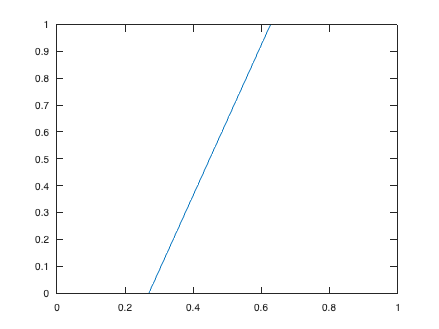

fnoutputs = '/Users/davidatkinson/Library/CloudStorage/OneDrive-UniversityCollegeLondon/data/verdictresultsfolder/res-2023-03-12T202054/outputs.mat' ;
S = load(fnoutputs,'vb0tot','fIC') ;
nsl = size(S.vb0tot,3) ;

sl = 8 ;


imgb0 = mat2gray(S.vb0tot) ;

fIC = S.fIC ;
fIC(fIC>1)=1;
fIC(fIC<0)=0;

xmid = 0.42;
grad = 2.8;

intc = xmid*(1-grad) ;

hfp = figure ;
xf = linspace(0,1,100);
y = grad*xf + intc ;
plot(xf,y)
axis([0 1 0 1])

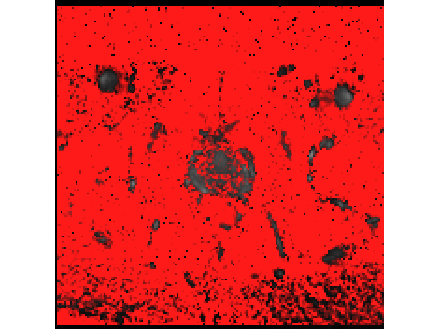


alphaOverlay = grad*fIC + intc ;
alphaOverlay(alphaOverlay<0)=0 ;
alphaOverlay(alphaOverlay>1)=1;

R = 1 ; G = 0.1 ; B = G ; % Slightly pink overlay colour
RBase = 0.9 ; GBase = RBase ; BBase = GBase ; % Base image 'colour'

overlayRGB = cat(4, R*ones(size(fIC)),G*ones(size(fIC)),B*ones(size(fIC))) ;
        
imgBaseRGB = cat(4, RBase*imgb0, GBase*imgb0, BBase*imgb0) ;

imgRGB = alphaOverlay.*overlayRGB + (1-alphaOverlay).*imgBaseRGB ;

hf = figure ;
imshow(squeeze(imgRGB(:,:,sl,:)))